Projekt: pole elektryczne wokół naładowanego koła

Parametry układu

% zakres osi 
x1 = -10;
x2 = 10;
y1 = -10;
y2 = 10;

% liczba punktów na jaką dzielimy koło
n = 100;

% promień koła
r = 5;

% pozycja
position = [0, 0];

% całkowity ładunek stałej gęstości powierzchniowej σ
charge = 10e-9;

% stała elektrostatyczna
k = 9e9;

Podział koła

% powierzchnia pojedyńczego punktu
point_area = (x2-x1)/(n-1) * (y2-y1)/(n-1);

% pole koła
area = pi*r^2;

% obliczenie ile punktów zmieści się w kole
number_of_points = area/point_area;

% obliczenie ładunku pojedyńczego punktu
point_charge = charge/number_of_points;

Stworzenie koła

% siatka
[X, Y] = meshgrid(linspace(x1, x2, n), linspace(y1, y2, n));

% wzór na koło
Z = (X-position(1)).^2 + (Y-position(2)).^2 - r^2;

% normalizacja
Z = abs(Z)./Z;

% transformacja żeby wnętrze koła było równe 1, a to co na zewnątrz równe 0
Z = (-Z+1)/2;

% wysokość koła ustawiamy na równą wartości pojedyńczego ładunku
Z = Z*point_charge;

Oblicznie natężenia pola elektrycznego 

% inicjalizacja tablic 
E_x_total = zeros(n, n);
E_y_total = zeros(n, n);
V_x_total = zeros(n, n);
V_y_total = zeros(n, n);

for i = 1:numel(Z) % pętla przechodząca przez wszystkie puntky siatki
  % obecny punkt
  point = [X(i), Y(i)];

  % odległość pomiędzy obecnym punktem, a resztą punktów
  r_x = X-point(1);
  r_y = Y-point(2);

  % prawdziwa odległość pomiędzy obecnym punktem, a resztą punktów
  r_c = sqrt((r_x.^2 + r_y.^2));

  %
  %  obliczanie natężenia pola elektrycznego
  %

  % siła pola elektrycznego wytwarzanego przez ten punkt (lokalizacja w tablicy) w bieżącym punkcie (ten powyżej)
  E_x = (k * Z .* r_x ./ r_c.^3);
  E_y = (k * Z .* r_y ./ r_c.^3);

  % we wzorze jest dzielenie przez 0 i powstaje trochę NaN, więc się ich pozbywamy
  E_x(i) = 0;
  E_y(i) = 0;

  % sumujemy wyniki wszystkich pól elektrycznych i otrzymujemy końcowe pole elektryczne działające na bieżący punkt
  E_x_total(i) = sum(E_x(:));
  E_y_total(i) = sum(E_y(:));

  %
  %  obliczanie potencjału pola elektrycznego
  %

  % obliczenia tykie same jak wyżej ale lekko inaczej tutaj
  V_x = (k * Z .* r_x ./ r_c.^2);
  V_y = (k * Z .* r_y ./ r_c.^2);

  V_x(i) = 0;
  V_y(i) = 0;

  V_x_total(i) = sum(V_x(:));
  V_y_total(i) = sum(V_y(:));

  % nadpisanie wartości pola elektrycznego w środku koła
  if Z(i) ~= 0 % matlab używa ~= zamiast !=
      E_x_total(i) = NaN; % aby środek kółka był pusty
      E_y_total(i) = NaN; % NaN aby na wykresie go nie rysowało
      V_x_total(i) = NaN;
      V_y_total(i) = NaN;
  end
end

% sumujemy pole działające w kierunkach x i y dla wykresu 3d natężenia pola elektrycznego
E_total = sqrt(E_x_total.^2 + E_y_total.^2);
V_total = sqrt(V_x_total.^2 + V_y_total.^2);

Wyresy natężenia pola elektrycznego

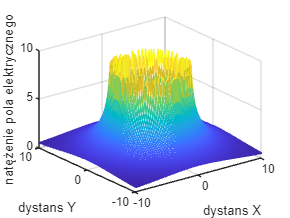

% wykres 3D

% nie jestem pewien czy jest potrzebny bo mamy narysowac rozklady natezenia
% i potencjalu w plaszczyznie
figure;
mesh(X, Y, E_total)
%title('')
xlabel("dystans X")
ylabel('dystans Y')
zlabel("natężenie pola elektrycznego")

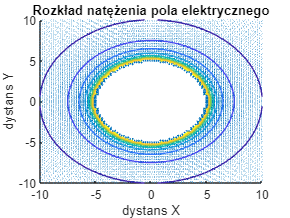


% wykres kierunków natężenia pola
figure;
hold on
quiver(X, Y, E_x_total, E_y_total)
contour(X, Y, E_total)
title('Rozkład natężenia pola elektrycznego')
xlabel("dystans X")
ylabel('dystans Y')
hold off

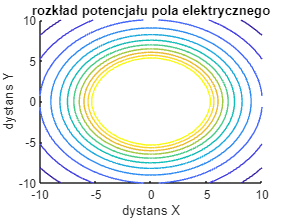


% wykres potencjału
figure;
hold on
contour(X, Y, V_total);
title("rozkład potencjału pola elektrycznego")
xlabel("dystans X")
ylabel("dystans Y")
hold off

Zadanie 2.

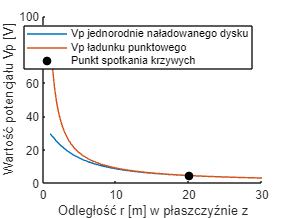

close all;

% Promień koła
r = 5;

% Całościowy ładunek q
charge = 10e-9;

% Powierzchnia koła (dysku)
area = pi*r^2;

% Stała elektrostatyczna
k = 9*10^9;

% Przedział z, dla którego obliczamy potencjał
z = linspace(1, 30, 100);

% Powierzchniowa gęstość ładunku (mała sigma)
surface_charge_density = charge/area;

% Potencjał w odległości z dla ładunku punktowego
V = (k*charge)./z;

% Potencjał w odległości z dla jednorodnie naładowanego dysku
Vp = k*2*pi*surface_charge_density*(sqrt((z.^2)+(r^2))-sqrt(z.^2));

% Wykres
figure
hold on
plot(z, Vp)
plot(z, V)
scatter(z(66), V(66), MarkerFaceColor='black', MarkerEdgeColor='black', Marker='o')
hold off

% Legenda wykresu
%title('')
xlabel('Odległość r [m] w płaszczyźnie z')
ylabel('Wartość potencjału Vp [V]')
legend('Vp jednorodnie naładowanego dysku', 'Vp ładunku punktowego', 'Punkt spotkania krzywych')


% Mniej więcej dla odległości 20 metrów można uznać taki dysk za ładunek punktowy


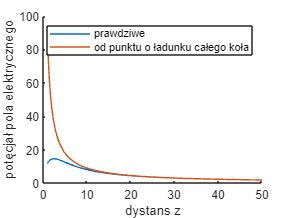

% parametry osi z
z1 = 1;
z2 = 50;
nz = 300;

% oś z
rz = linspace(z1, z2, nz);

% inicjalizacja macierzy
sum_x = zeros(1, nz);
sum_y = zeros(1, nz);
sum_z = zeros(1, nz);

for i = 1:numel(rz)
    
    % koordynaty obecnego punktu
    point = [0, 0, rz(i)];
    
    % dystanse w osiach pomiędzy obecnym punktem a punktami na siatce
    r_x = point(1)-X;
    r_y = point(2)-Y;
    r_z = point(3);
    
    % prawdziwy dystans pomiędzy obecnym punktem a punktami na siatce
    r = sqrt(r_x.^2 + r_y.^2 + r_z^2);
    
    % potencjał w każdej osi
    E_x = k * Z .* r_x ./ r.^2;
    E_y = k * Z .* r_y ./ r.^2;
    E_z = k * Z  * r_z ./ r.^2;

    % suma potencjału w każdej osi
    sum_x(i) = sum(E_x(:));
    sum_y(i) = sum(E_y(:));
    sum_z(i) = sum(E_z(:));

end

% prawdziwa wartość potencjału
E_z_total = sqrt(sum_x.^2 + sum_y.^2 + sum_z.^2);

% potencjał obliczony gdyby koło było punktem
V = k * charge ./rz;
figure;
hold on
plot(rz, E_z_total);
plot(rz, V);

legend("prawdziwe", "od punktu o ładunku całego koła")
xlabel("dystans z")
ylabel("potęcjał pola elektrycznego")


hold off